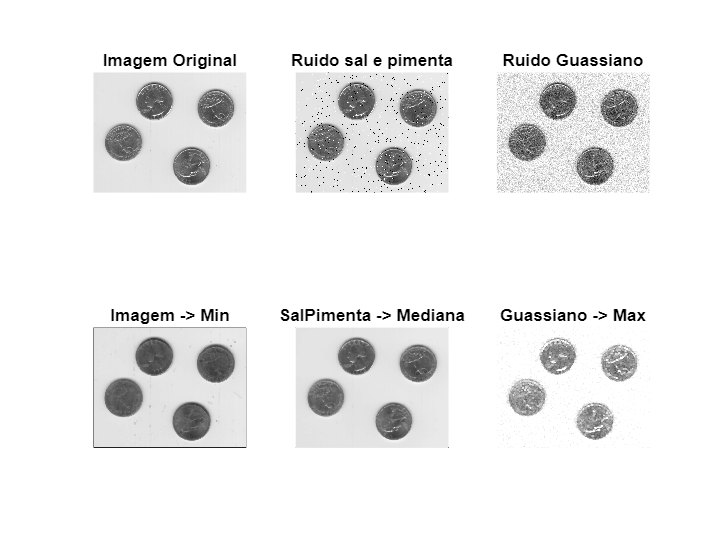

clear

I = imread('eight.tif');
subplot(2,3,1), imshow(I); title('Imagem Original');
I_m = ordfilt2(I, 1, ones(3,3));
subplot(2,3,4), imshow(I_m); title('Imagem -> Min');

Isp = imread('eightSaltPepper.tif');
subplot(2,3,2), imshow(Isp); title('Ruido sal e pimenta');
Isp_m = ordfilt2(Isp, 5, ones(3,3));
subplot(2,3,5), imshow(Isp_m); title('SalPimenta -> Mediana');

Ig = imread('eightGuassian.tif');
subplot(2,3,3), imshow(Ig); title('Ruido Guassiano');
Ig_m = ordfilt2(Ig, 9, ones(3,3));
subplot(2,3,6), imshow(Ig_m); title('Guassiano -> Max');